clear all;
clc;
 
 
% Load training and test data using |imageDatastore|.
syntheticDir   = fullfile(toolboxdir('vision'),'visiondata','digits','synthetic');
handwrittenDir = fullfile(toolboxdir('vision'),'visiondata','digits','handwritten');
 
 
% |imageDatastore| recursively scans the directory tree containing the
% images. Folder names are automatically used as labels for each image.
trainingSet = imageDatastore(syntheticDir,'IncludeSubfolders',true,'LabelSource','foldernames');
testSet     = imageDatastore(handwrittenDir,'IncludeSubfolders',true,'LabelSource','foldernames');

countEachLabel(trainingSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       101 
      1       101 
      2       101 
      3       101 
      4       101 
      5       101 
      6       101 
      7       101 
      8       101 
      9       101 


countEachLabel(testSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       12  
      1       12  
      2       12  
      3       12  
      4       12  
      5       12  
      6       12  
      7       12  
      8       12  
      9       12  


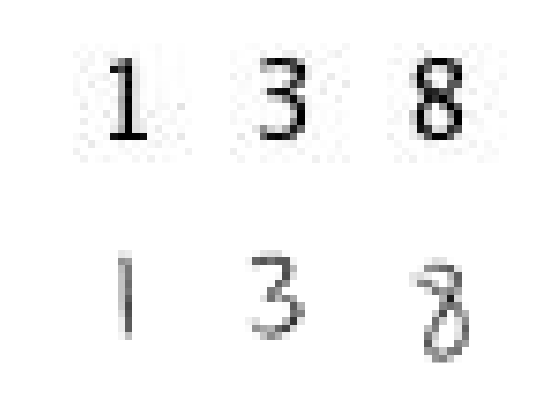

figure;
 
 
subplot(2,3,1);
imshow(trainingSet.Files{102});
 
 
subplot(2,3,2);
imshow(trainingSet.Files{304});
 
 
subplot(2,3,3);
imshow(trainingSet.Files{809});
 
 
subplot(2,3,4);
imshow(testSet.Files{13});
 
 
subplot(2,3,5);
imshow(testSet.Files{37});
 
 
subplot(2,3,6);
imshow(testSet.Files{97});

% Loop over the trainingSet and extract pixel values as features from each image. A
% similar procedure will be used to extract features from the testSet.
 
 
numTrainImages = numel(trainingSet.Files);
 
 
temp = readimage(trainingSet,3); % randomly reading an image in the training set (here it is the 1st image in the training set, hence 1)
imgSize=size(temp);
featureLength=prod(imgSize);
trainingFeatures = zeros(numTrainImages,featureLength);
 
 
for i = 1:numTrainImages
    img = readimage(trainingSet,i);
    pixelValuesSingleRowTrain=reshape(img,1,featureLength);
    trainingFeatures(i, :) = pixelValuesSingleRowTrain;  
end
 
 
% Get labels for each image.
trainingLabels = trainingSet.Labels;

kNNclassifier = fitcknn(trainingFeatures, trainingLabels,'NumNeighbors',7);

inSamplePrediction=predict(KNNclassifier,trainingFeatures);

Unrecognized function or variable 'KNNclassifier'.

inSampleConfusionMatrix=confusionmat(trainingLabels,inSamplePrediction)

numTestImages = numel(testSet.Files);
testFeatures = zeros(numTestImages,featureLength);
for i = 1:numTestImages
    imgTest = readimage(testSet,i);
    pixelValuesSingleRowTest=reshape(imgTest,1,featureLength);
    testFeatures(i, :) = pixelValuesSingleRowTest;  
end
 
 
% Get labels for each image.
testLabels = testSet.Labels;
 
 
% Make class predictions using the test features.
outSamplePrediction = predict(KNNclassifier,testFeatures);
 
 
% Tabulate the results using a confusion matrix.
outSampleConfusionMatrix = confusionmat(testLabels, outSamplePrediction)

accuracyTrain=sum(diag(inSampleConfusionMatrix))/sum(sum(inSampleConfusionMatrix))

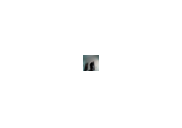

camList=webcamlist;
cam = webcam(camList{1,1});
temp = snapshot(cam);
clear('cam');
%tempGray = im2gray(temp);
%img=imresize(tempGray,[16,16]);
img=imresize(temp,'OutputSize',[16,16]);
figure
imshow(img)

 
 
 
pixelValuesSingleRowDeployed=reshape(img,1,featureLength);
 
 
deploymentSamplePrediction = predict(kNNclassifier,pixelValuesSingleRowDeployed)

deploymentSamplePrediction = categorical
     6 
